MEAN FILTERING - SMOOTHENING

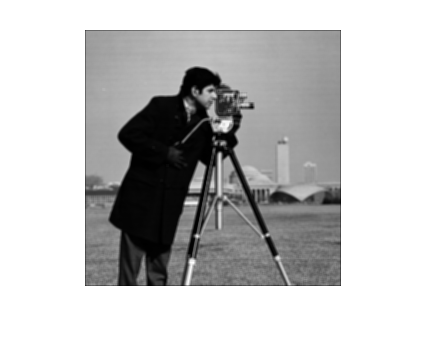

i = imread('Cameraman.tif');
i = double(i);
[m,n] = size(i);
mask = (1/9)*ones(3,3);
new = conv2(i,mask,'same');
imshow(new,[]);

MEDIAN FILTERING - SMOOTHENING

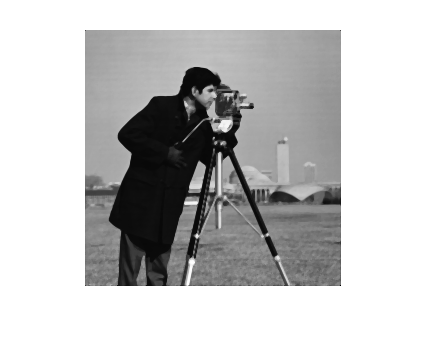

i = imread('Cameraman.tif');
[m,n] = size(i);
mask = ones(3,3);
g = i;
g = [zeros(m,1),g];     %for adding columns
g = [g, zeros(m,1)];
g = [zeros(1,n+2);g];  %for adding rows
g = [g;zeros(1,n+2)];
new = zeros(m,n);
for p = 2:m+1
    for q = 2:n+1
        val = [];
         for r = -1:1
            for s = -1:1
                %disp(val)
                val= [val (g(p+r,q+s))];  %for making the vector for median function application
            end
         end
         
         new(p-1,q-1) = median(val(2:end));
    end
end
imshow(new,[]);

SPATIAL SHARPENING FILTER

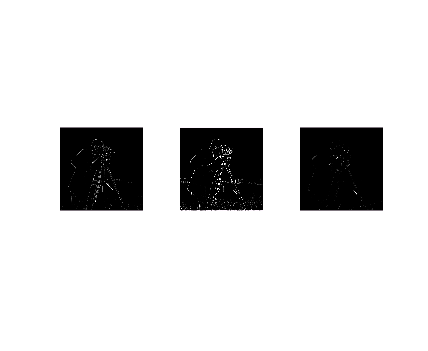

i = imread('Cameraman.tif');
i = double(i);
i1 = histeq(i);
[m,n] = size(i);
mask1 = [0 1 0; 1 -4 1; 0 1 0];
mask2 = [-1 -1 -1;-1 8 -1;-1 -1 -1];
mask3 = [1 -2 1;-2 4 -2;1 -2 1];
new1 = conv2(i,mask1,'same');
new2 = conv2(i,mask2,'same');
new3 = conv2(i,mask3,'same');
subplot(1,3,1);
imshow(new1-i,[0 255]);
subplot(1,3,2);
imshow(new2-i,[0 255]);
subplot(1,3,3);
imshow(new3-i,[0 255]);

UN SHARPENING AND SHARPENING

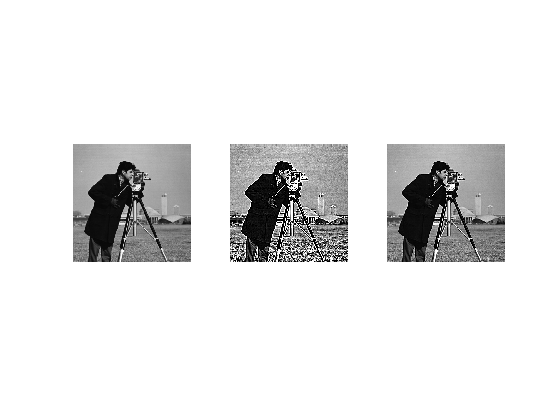

i = imread('Cameraman.tif');
i = double(i);
i1 = histeq(i);
[m,n] = size(i);
mask = [-1 -1 -1; -1 8 -1; -1 -1 -1 ];
g = i;
g = [zeros(m,1),g];     %for adding columns
g = [g, zeros(m,1)];
g = [zeros(1,n+2);g];  %for adding rows
g = [g;zeros(1,n+2)];
g(1,:) = g(2,:);
g(258,:) = g(257,:);        % for getting the edge values
g(:,1) = g(:,2);
g(:,258) = g(:,257);
new1 = zeros(m,n);
new2 = zeros(m,n);
for p = 2:m+1
    for q = 2:n+1
        val = 0.0;
         for r = -1:1
            for s = -1:1
                val= val + double((g(p+r,q+s)));
            end
         end
         val2 = g(p-1:p+1,q-1:q+1);
         new2(p-1,q-1) = sum(sum(val2.*mask));
         new1(p-1,q-1) = val/9;
    end
end
new1 = i - new1;
new2 = new2 +i;
new1 = new1+i;
figure
subplot(1,3,3);
imshow(new1,[0 255]);
subplot(1,3,1);
imshow(i,[0 255]);
subplot(1,3,2);
imshow(new2,[0 255]);  %using edge detection mask and adding to original image

LOW PASS FILTER

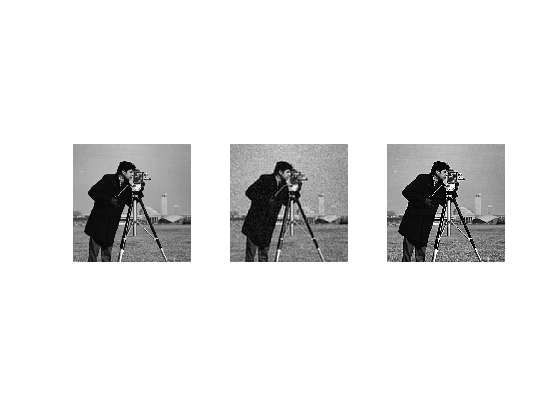

i = imread('Cameraman.tif');
i1 = imnoise(i,'gaussian',0,0.01);
[m,n] = size(i);
maskf = zeros(m,n);
temp = ones(m,n);

x = zeros(m,n);
for p = 1:m
    for q = 1:n
        if sqrt(((p-(m/2))^2) + ((q-(n/2))^2)) < 50
           x(p,q) = 1;                              %for circular filter
        end
    end
end

i1 = fft2(i1);
i1 = fftshift(i1);
val = i1.*x;
val = ifft2(ifftshift(val));
val = abs(val);
imshow(val,[0 255]);

BUTTERWORTH LOW PASS FILTER

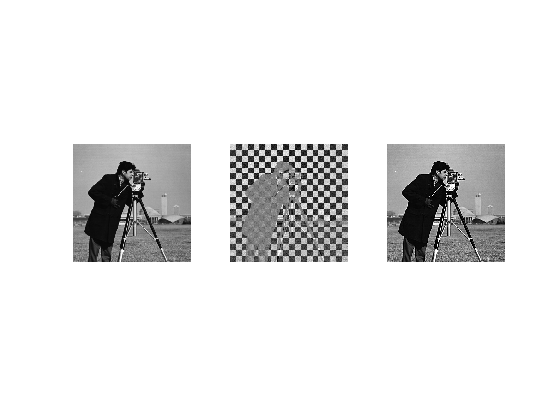

i = imread('Cameraman.tif');
i1 = imnoise(i,'gaussian',0,0.01);
imshow(i1,[]);
[m,n] = size(i);
i1 = fft2(i1);                       % frequency plot centred around the axes from centre of image
i1 = fftshift(i1);                   %shifted to avoid repeating freq
mask = zeros(m,n);
for p = 1:m
   for q = 1:n
       val = sqrt(((p-(m/2))^2) + ((q-(n/2))^2));
       div = (val/1000)^2;
       mask(p,q) = 1/(1+div);
   end
end
i1 = i1.*mask;
i1 = ifft2(i1);
imshow(i1,[]);

LAPLACIAN OF GAUSSIAN - SMOOTHENING AND EDGE DETECTION

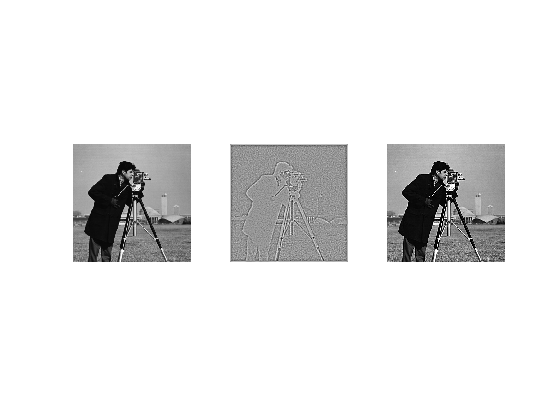

i = imread('Cameraman.tif');
i1 = imnoise(i,'gaussian',0,0.01);
i1=double(i1);
[m,n] = size(i);                 
i2 = zeros(m,n);
i3 = zeros(m,n);
maskg = [1 4 7 4 1;4 16 26 16 4;7 26 41 26 7;4 16 26 16 4;1 4 7 4 1];
maskg = maskg/273;
maskl = [0 1 0;1 -4 1;0 1 0];
i2 = conv2(i1,maskg);
i3 = conv2(i2,maskl);
imshow(i3,[]);

SOBEL FILTER

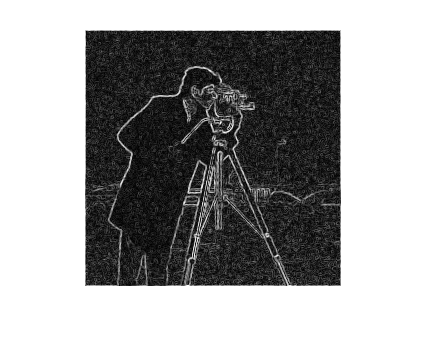

clear all;
close all;
i = imread('Cameraman.tif');
i1 = imnoise(i,'gaussian');
i1 = double(i1);
mgx = [-1 0 1;-2 0 2;-1 0 1];
mgy = [-1 -2 -1;0 0 0;1 2 1];
gx = conv2(i1,mgx,'same');
gy = conv2(i1,mgy,'same');
i2 = sqrt((gx.*gx)+(gy.*gy));
figure,imshow(i2,[]);

DILATION

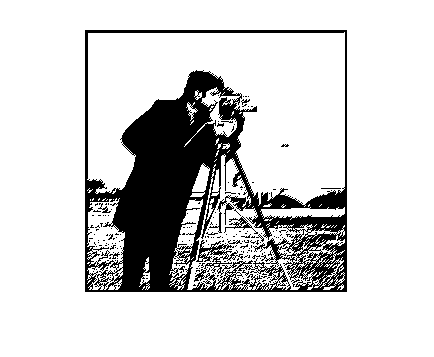

i = imread('Cameraman.tif');
i = im2bw(i);
[m,n] = size(i);
dilate = rot90(eye(3));
dm = size(dilate,1);
i1 = zeros(m+(2*dm),n+(2*dm));
i2 = im2bw(i1);
i1(dm+1:dm+m,dm+1:dm+n) = i;
i1 = im2bw(i1);
dilate = im2bw(dilate);
org = (dm+1)/2;
d = floor((org+1)/2);
for p = 1:m
    for q = 1:n
        if dilate(org,org) == i(p,q)
            i2(p+dm-d:p+dm+d,q+dm-d:q+dm+d) = i1(p+dm-d:p+dm+d,q+dm-d:q+dm+d) + dilate;
        end
    end
end
imshow(i2);

Simple Global thresholding

i = imread('Cameraman.tif');
a = 1:256;
[m,n] = size(i);
h = imhist(i);
t = 0;
tn=105;
while tn~=t
    t=tn;
    Mean_val=[sum(a(1:tn)*h(1:tn))/(sum(h(1:tn))),sum(a(tn:256)*h(tn:256))/(sum(h(tn:256)))];
    tn=mean(Mean_val);
end 

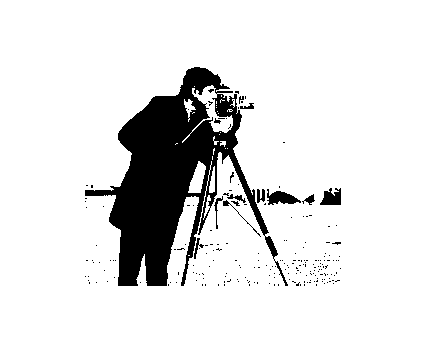

i = (i>=tn);
imshow(i,[]);

Otsu's method

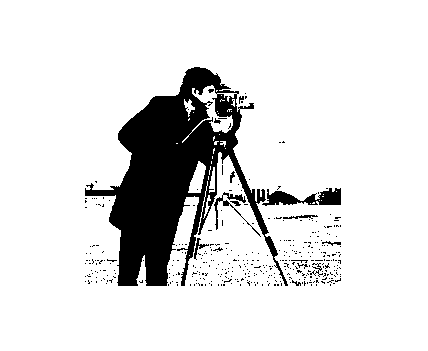

i = imread('Cameraman.tif');
[m,n] = size(i);
h = imhist(i);
tot = sum(h);
check = zeros(1,253);
for t=2:254
    w0 = sum(h(1:t));
    w1 = sum(h(t+1:256));
    sigma0 = var(h(1:t));
    sigma1 = var(h(t+1:255));
    check(t-1) = (w0*sigma0^2) + (w1*sigma1^2);
end
[val,ind] = min(check);
i = i>=ind;
imshow(i,[]);

K Means Clustering

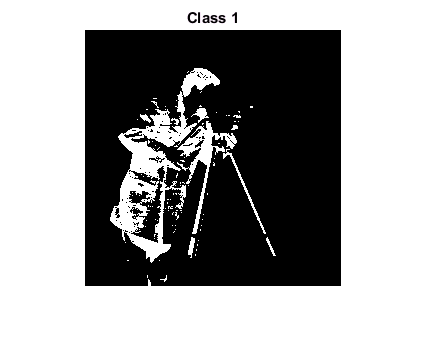

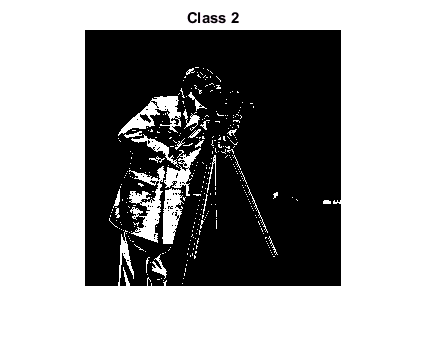

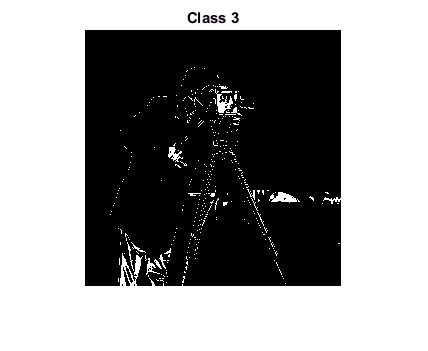

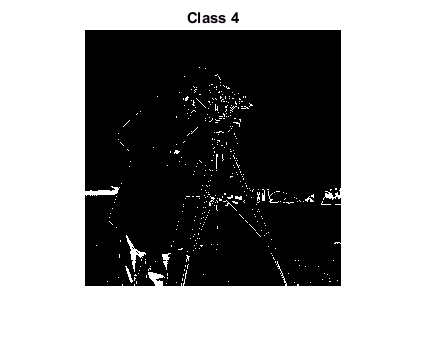

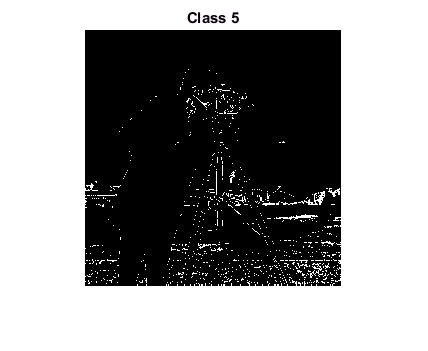

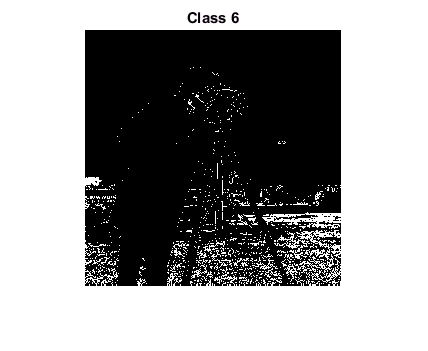

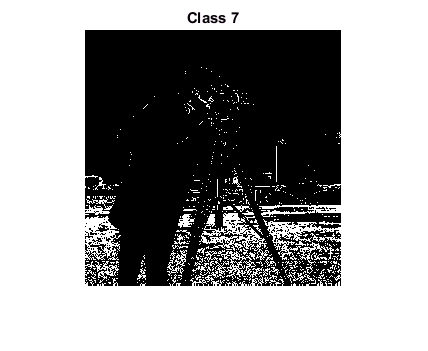

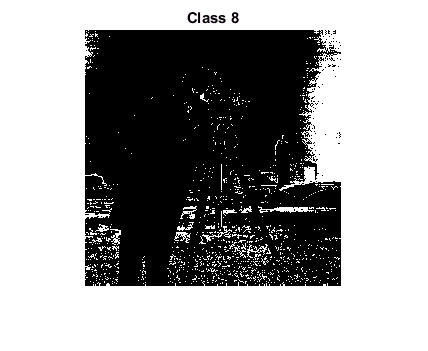

img = imread('Cameraman.tif');
img = double(img);
[m,n] = size(img);
length = m*n;
iter = 100;
img = reshape(img,[1,length]);
k = 12;
count = zeros(1,k);
centroids = 1:(255)/(k):255;
centroids = floor(centroids);
updated = zeros(1,k);
class = zeros(length,2);
while centroids ~= updated & iter >= 0
   updated = centroids;
   count = zeros(1,k);
    for i=1:length
        val = zeros(k,1);
        for j = 1:k
            val(j) = abs(centroids(j) - img(i));
        end
        [val,ind] = min(val);
        class(i,1) = ind;
        class(i,2) = img(i);
    end
    updated = zeros(1,k);
    for j = 1:length
        count(class(j,1)) = count(class(j,1)) +1;
        updated(class(j,1)) = updated(class(j,1)) + class(j,2);
    end
    temp = centroids;
    centroids = floor(updated./count);
    upated = temp;
    iter = iter-1;
end
for i = 1:k
    for j = 1:length
        if class(j,1) == i
            img(j) = 1;
        else
            img(j) = 0;
        end
    end
    figure,imshow(reshape(img,[m,n]),[])
    title(['Class ',num2str(i)]);
end

Harris edge detection

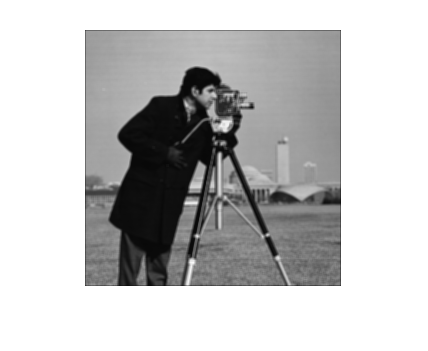

img = imread('cameraman.tif');
img = double(img);
img_new = img;
[m,n] = size(img);
r = zeros(m,n);
lambda = 0.04;
t = 10000000;
mask_mean = (1/9)*ones(3,3);
img = conv2(img,mask_mean,'same');
maskx = [1 0 -1;2 0 -2;1 0 -1];
masky = [1 2 1;0 0 0;-1 -2 -1];
mask = [0 1 0;1 -4 1;0 1 0];
ix = conv2(img,maskx,'same');
iy = conv2(img,masky,'same');
h = zeros(2,2);
ix2 = ix.*ix;
iy2 = iy.*iy;
ixy = ix.*iy;
sx2 = conv2(ix2,mask,'same');
sy2 = conv2(iy2,mask,'same');
sxy = conv2(ixy,mask,'same');
for i = 1:m
    for j =1:n
        h = [sx2(i,j) sxy(i,j);sxy(i,j) sy2(i,j)];
        r(i,j) = det(h) - lambda*(trace(h)^2);
    end
end
img_new = (r>t);
corner = zeros(m,n,3);
corner(:,:,1) = img_new*255;
img = uint8(img);
temp = zeros(m,n,3);
temp(:,:,1) = img;
temp(:,:,2) = img;
temp(:,:,3) = img;
temp = uint8(temp);
corner = uint8(corner);
figure,imshow(temp,[]);

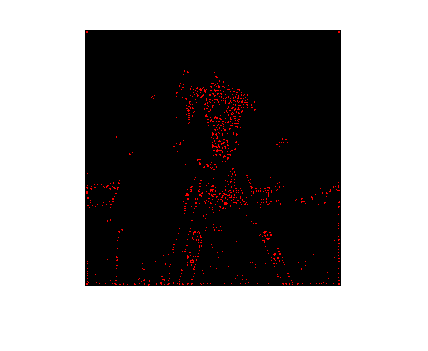

figure,imshow(corner,[]);

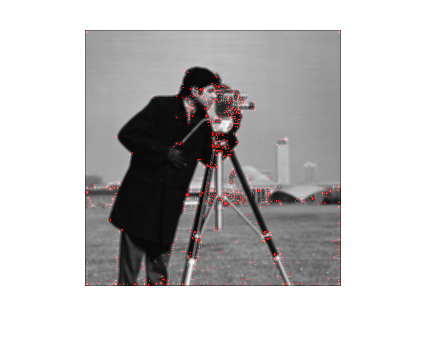

figure,imshow(corner+temp,[]);